# Week 3: Rigid Motions Review

### Author: Keith Chester

#### E-mail: kchester@wpi.edu

## Introduction

In the third week of *RBE 500 - Foundations of Robotics*, we review material covered in Chapter 2 of the book *Robot Modeling and Control* *(2nd edition) *to ensure our understanding. To demonstrate this, we will be looking again at rotation matricies, homogeneous transformations, and performing an import real-life exercise of creating homogeneous transforms from a blueprint design.

### III-1

In our first problem, we know of three frames - $o_1 x_1 y_1 z_1$, $o_2 x_2 y_2 z_2$, and $o_3 x_3 y_3 z_3$. Between these frames, we know two rotation matricies:

$R_2^1 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \frac{1}{2} & -\frac{\textrm{sqrt}\left(3\right)}{2}\\
0 & \frac{\textrm{sqrt}\left(3\right)}{2} & \frac{1}{2}
\end{array}\right\rbrack$ and $R_3^1 =\left\lbrack \begin{array}{ccc}
0 & 0 & -1\\
0 & 1 & 0\\
1 & 0 & 0
\end{array}\right\rbrack$ 

Given this, determine the rotation matrix $R_3^2$.

### III-2

In this problem, we see *Figure 1*, below:

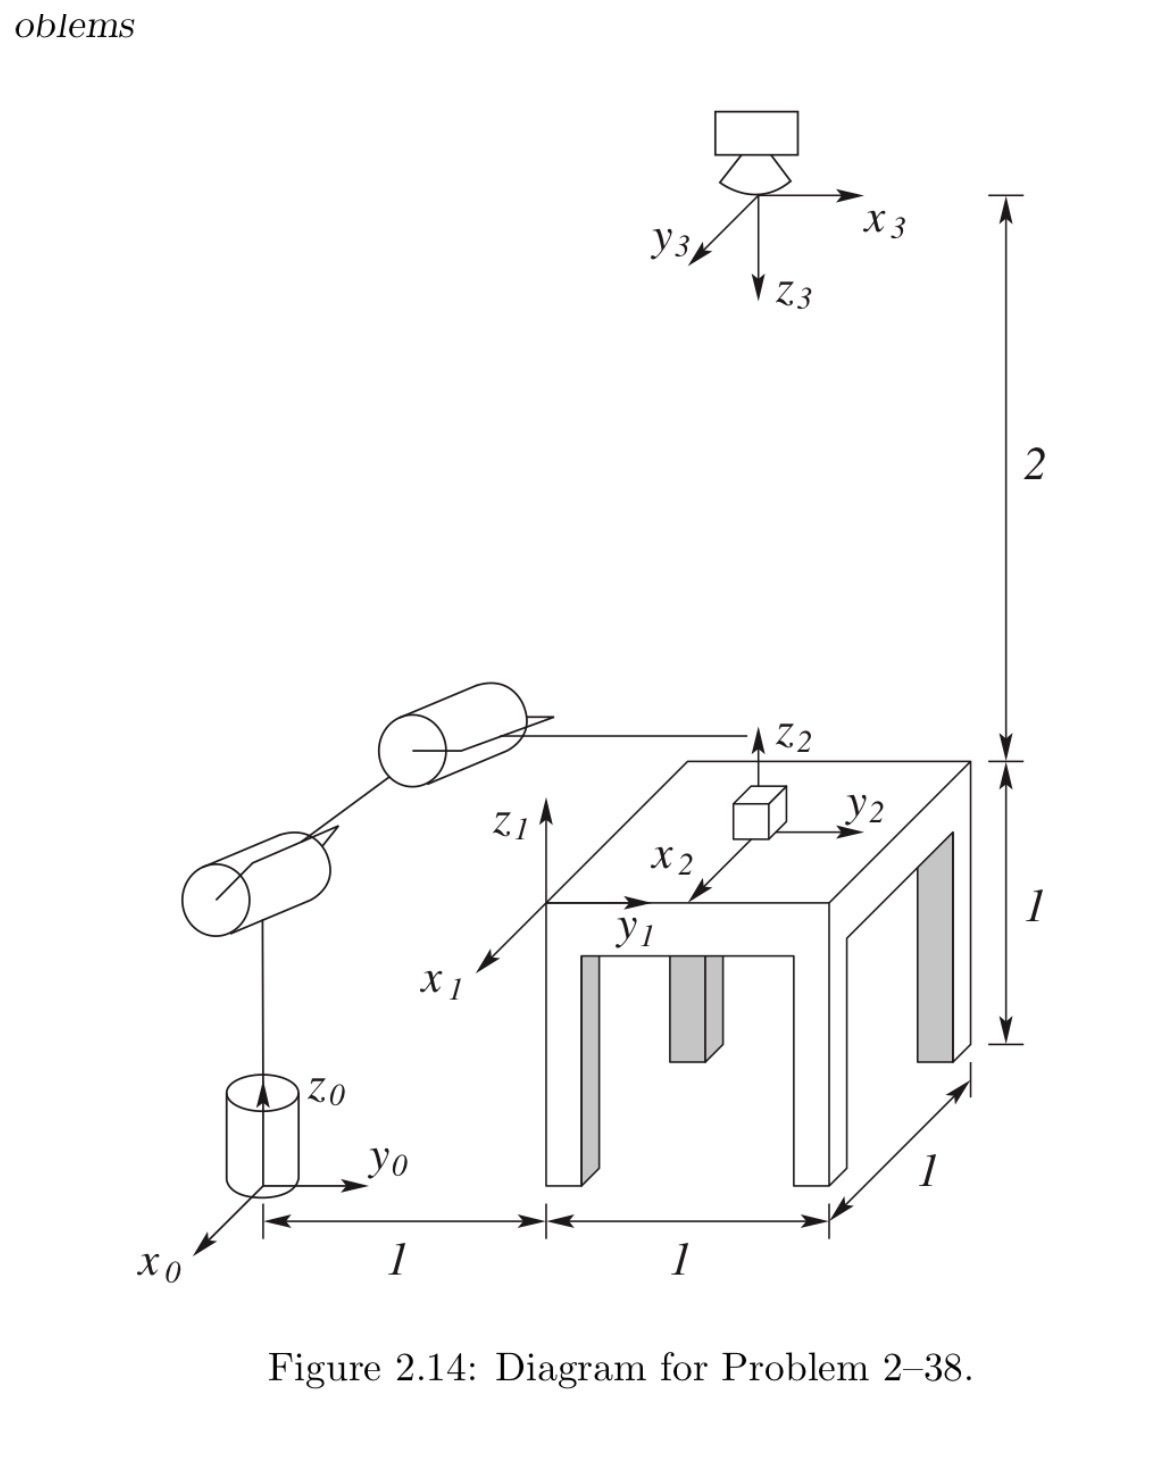

*Figure 1: Figure 2.14 from Robot Modeling and Control, 2nd edition, page 73*

Given the measurements provided between each coordinate frame, define a homogeneous transformation for each frame back to $o_0 x_0 y_0 z_0$. After this, use known information to derive a homogeneous transformation from $o_2 x_2 y_2 z_2$ to $o_3 x_3 y_3 z_3$.

### III-3

In this problem, we are given *Figure 2* and directed to find a transform $H_4^0$ for frames $o_0 x_0 y_0 z_0$ to $o_4 x_4 y_4 z_4$.

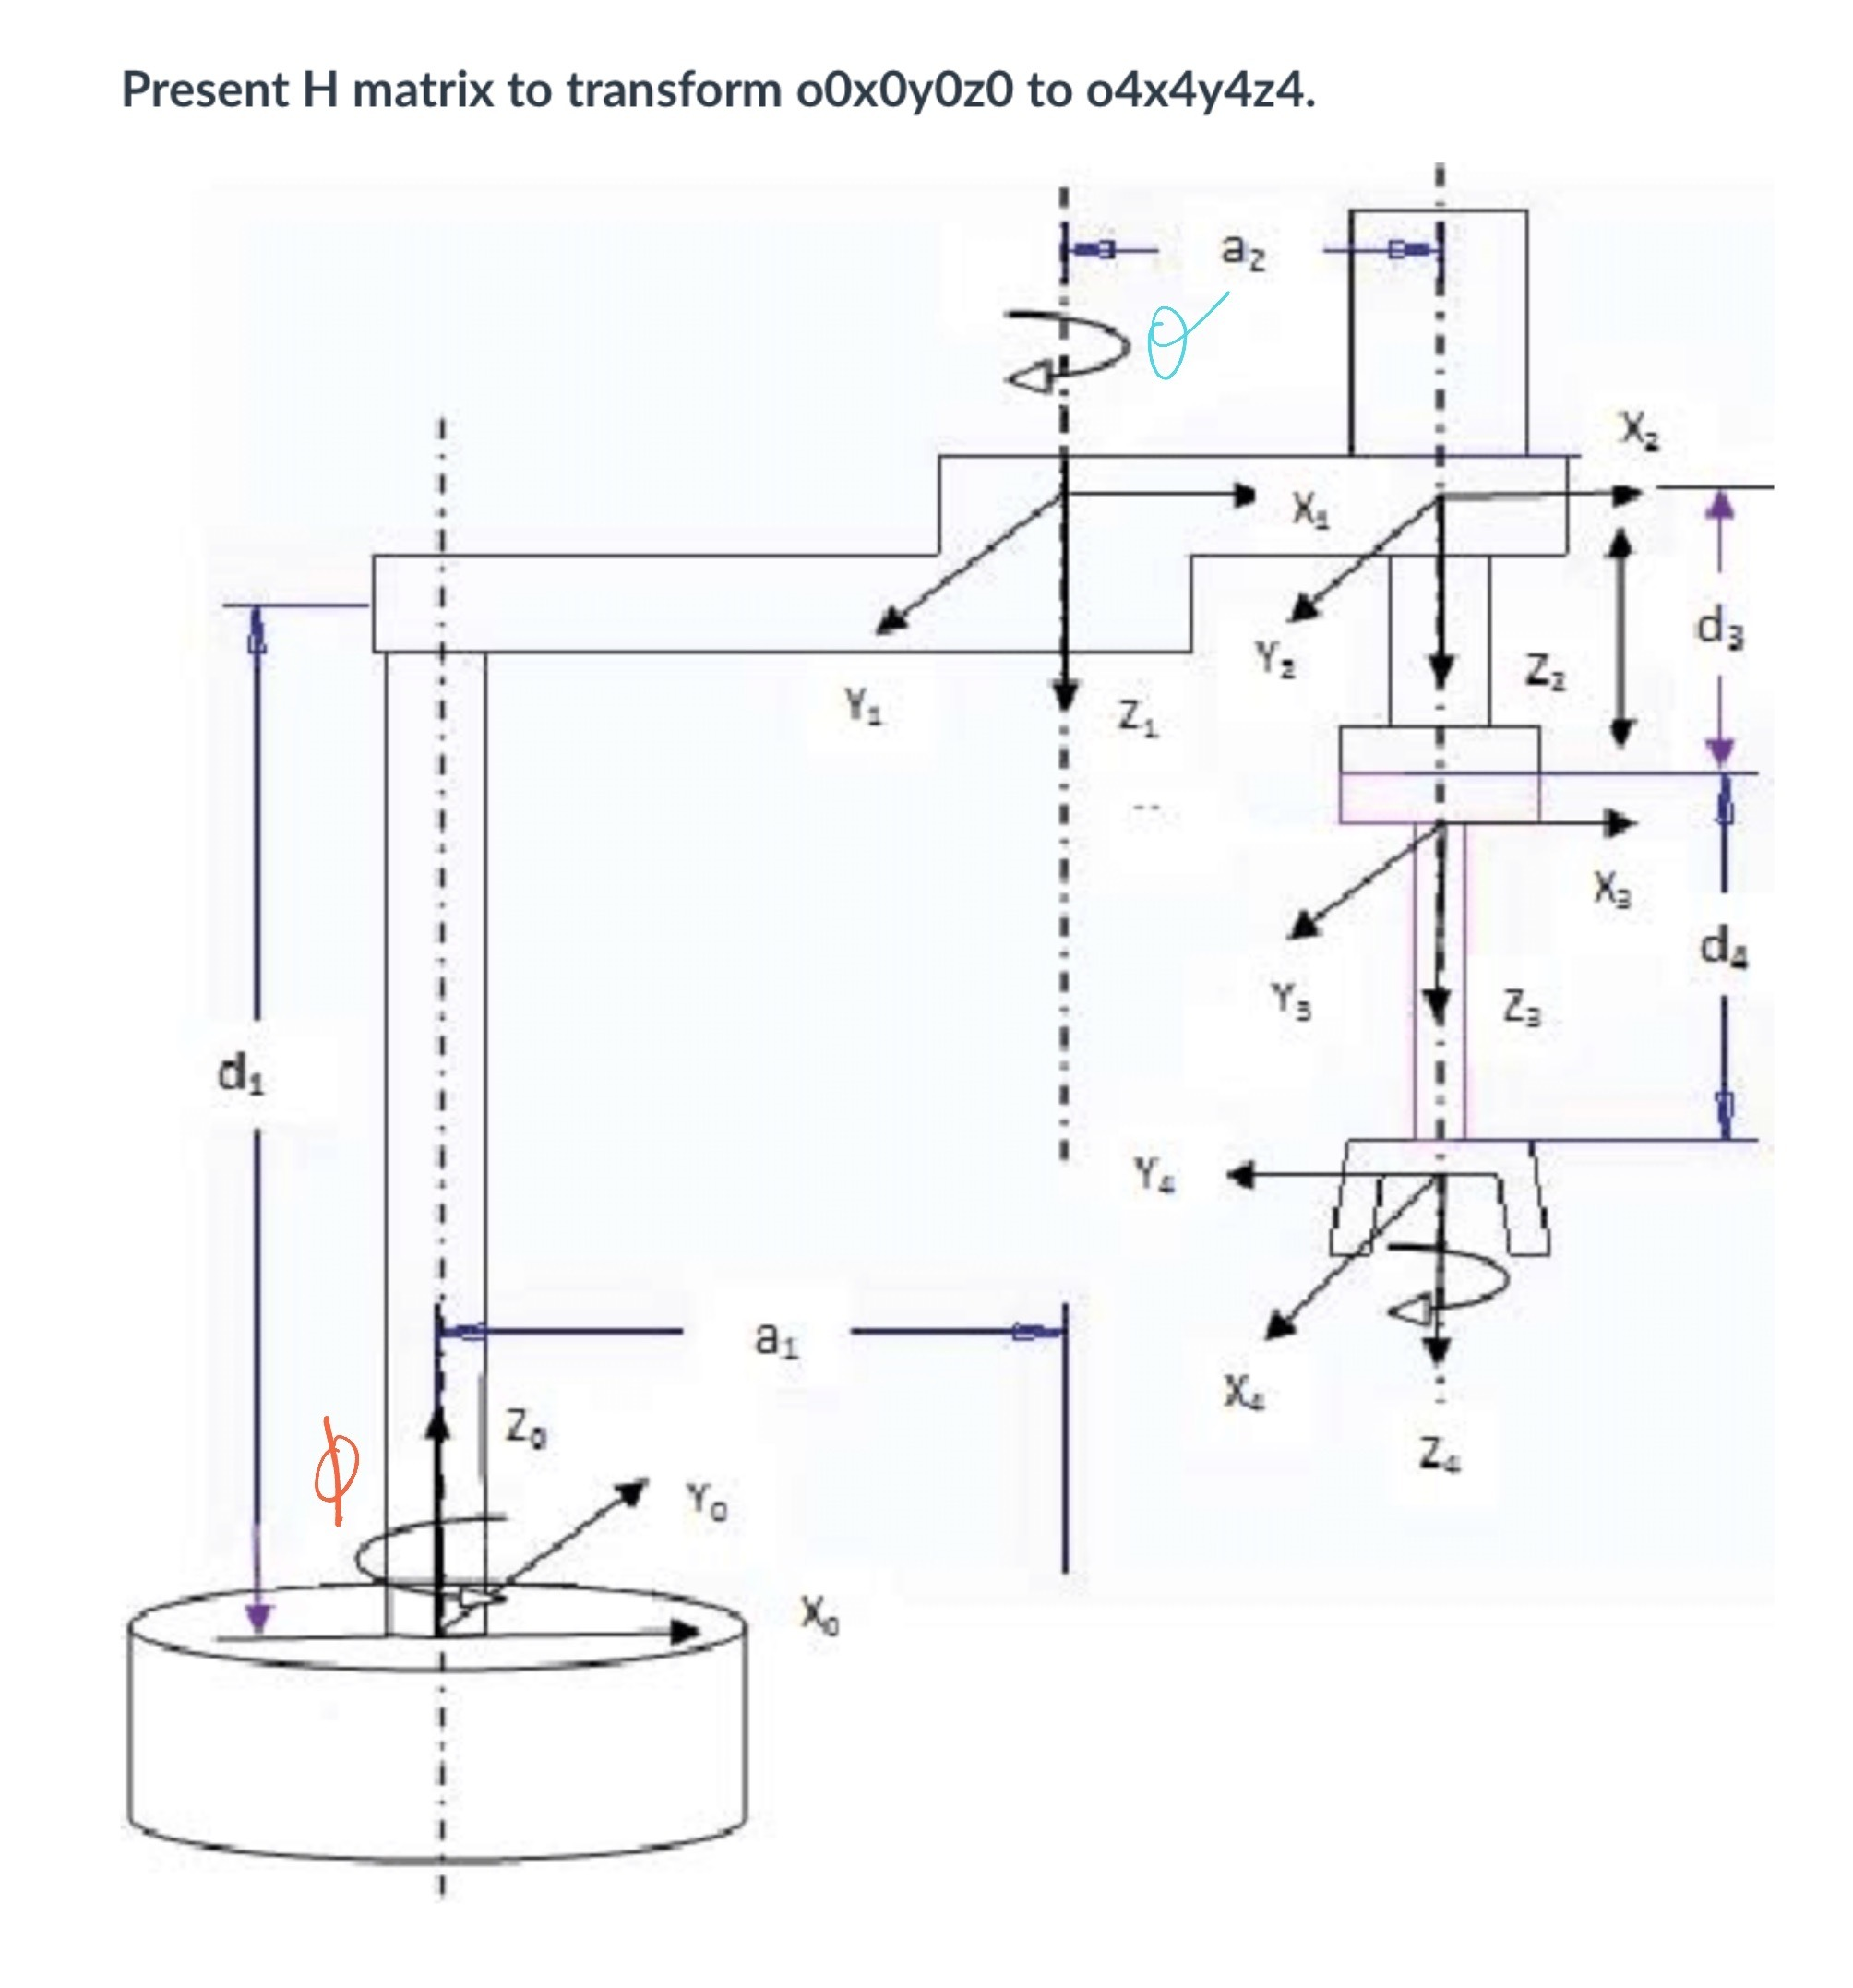

*Figure 2: A double-plunger style robotic arm.*

## Methods

In this section we will discuss how we approached and performed each problem.

### III-1

We are given two rotations, $R_2^1$ and $R_3^1$. From this information, we wish to calculate$R_3^2$. To calculate this, we will be consider the following properties of matricies:


$$A^{-1} A=I$$


*Equation 1: Matrix Inverse Identity*

A matrix multiplied by its inverse results in an identity matrix. In rotation matricies, calculating the inverse is simple, as it is simply:


$$R^T =R^{-1}$$


*Equation 2: Rotation matrix inverse*

With this in mind, we can then consider that for a given set of matricies, *A*, *B*, and *C*, where *A* and *C* are known quantities, but *A* is to be solved for, we can make use of *Equation 1* to do the following:


$$\begin{array}{l}
C=A\;B\\
A^{-1} \;C=A^{-1} A\;B\\
A^{-1} C=I\;B\\
A^{-1} C=B
\end{array}$$


*Equation 3: Solving for an unknown matrix*

Thus, we can use our rotation matricies to create the following equation:


$$\begin{array}{l}
R_3^1 =R_2^1 R_3^2 \\
{R_2^1 }^{-1} R_3^1 ={R_2^1 }^{-1} \;R_2^1 R_3^2 \\
{R_2^1 }^{-1} R_3^1 =IR_3^2 \\
{R_2^1 }^{-1} R_3^1 =R_3^2 
\end{array}$$


*Equation 4: Solving for *$R_3^2$

...and with that, we have solved for $R_3^2$.

### III-2

To begin this problem, we first define the homogenous transforms for each frame. This is done by looking at Figure 1 above and considering the measurements and axis orientations presented. From this we can create the following homogeneous calculations.

$H_1^0$ = $\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 1\\
0 & 0 & 1 & 1\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$    $H_2^0$ = $\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & -\frac{1}{2}\\
0 & 1 & 0 & \frac{3}{2}\\
0 & 0 & 1 & 1+\frac{10}{100}\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$    $H_3^0$ = $\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & -\frac{1}{2}\\
1 & 0 & 0 & \frac{3}{2}\\
0 & 0 & -1 & 3\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

*Equation 5: Homogeneous transformations for III-2*

These homogeneous transforms are determined by observing differences between the coordinate axes and their locations relative to one another. The rotation in $H_3^0$ is noteworthy as it is more compicated than a singular rotation. It was calculated by performing current frame rotations around the *z* axis -90 degrees, and then the *y* axis 180 degrees.


$$\begin{array}{l}
R_3^0 =\;R_{z,-90} R_{y,180} =\left\lbrack \begin{array}{ccc}
\cos \left(-90\right) & -\sin \left(-90\right) & 0\\
\sin \left(-90\right) & \cos \left(-90\right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
\cos \left(180\right) & 0 & \sin \left(180\right)\\
0 & 1 & 0\\
-\sin \left(180\right) & 0 & \cos \left(180\right)
\end{array}\right\rbrack \\
=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
-1 & 0 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
-1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & -1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
1 & 0 & 0\\
0 & 0 & -1
\end{array}\right\rbrack 
\end{array}$$


*Equation 6: Calculating *$R_3^0$ 

To determine $H_3^2$, we can look at our available homogenous transformations as a directed graph. Let us observe the problem again with our transformations mapped on it:

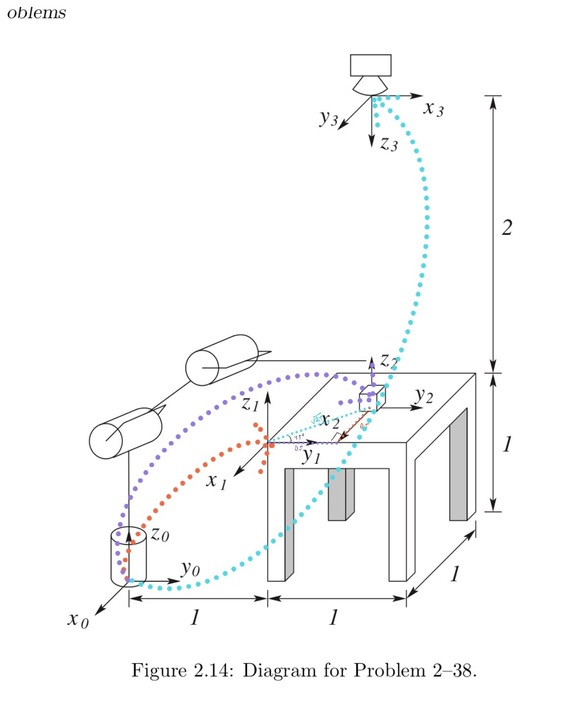

*Figure 3: Figure 1, presented wth homogeneous transformations overlayed as directional arrows*

In this approach, we can look at a path over these transformations from $o_2 x_2 y_2 z_2$ to $o_3 x_3 y_3 z_3$. If we move over a transform on this path in its intended direction (point to tip of the arrow), then we apply the transformation as intended. If we move overa transformation in reverse (tip of the arrow to its origin point) then we perform the inverse of that transformation.

The existing path for us is to go from $o_2 x_2 y_2 z_2$ to $o_1 x_1 y_1 z_1$ via the ${H_2^0 }^{-1}$transform, and then move to $o_3 x_3 y_3 z_3$ via the ${H_3^0 }$transform. Thus, our desired result can be calculated as:


$$H_3^2 ={H_2^0 }^{-1} H_3^0$$


*Equation 7: Calculating *$H_3^2$

### III-3

By observing the rotational differences between presented coordinate axes, and noting the included measurements on the diagram in *Figure 2*, we can begin to form homogenous transformations, moving methodically from one frame to the next along the arm:


$$\begin{array}{l}
H_1^0 =\left\lbrack \begin{array}{cc}
R_1^0  & d_1^0 \\
0 & 1
\end{array}\right\rbrack \\
R_1^0 =R_{z,\phi } R_{x,180} =\left\lbrack \begin{array}{ccc}
\cos \left(\phi \right) & -\sin \left(\phi \right) & 0\\
\sin \left(\phi \right) & \cos \left(\phi \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \left(180\right) & -\sin \left(180\right)\\
0 & \sin \left(180\right) & \cos \left(180\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \left(\phi \right) & \sin \left(\phi \right) & 0\\
\sin \left(\phi \right) & -\cos \left(\phi \right) & 0\\
0 & 0 & -1
\end{array}\right\rbrack \\
H_1^0 =\left\lbrack \begin{array}{cccc}
\cos \left(\phi \right) & \sin \left(\phi \right) & 0 & \cos \left(\phi \right)a_1 \\
\sin \left(\phi \right) & -\cos \left(\phi \right) & 0 & \sin \left(\phi \right)a_1 \\
0 & 0 & -1 & d_1 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \\
H_2^1 =\left\lbrack \begin{array}{cccc}
\cos \left(\theta \right) & -\sin \left(\theta \right) & 0 & \cos \left(\theta \right)a_2 \\
\sin \left(\theta \right) & \cos \left(\theta \right) & 0 & \sin \left(\theta \right)a_2 \\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \\
H_3^2 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_3 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \\
H_4^3 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_4 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack 
\end{array}$$


*Equation 8: Presenting all homogeneous transformations for III-3*

The rotation for $H_1^0$ is complicated, presented as a rotation along the *z* axis $\phi$ degrees, and rotated 180 degrees around the *x* axis. It's expansion and resulting rotation matrix is presented above.

To solve for $H_4^0$, we merely chain together all rotations as follows:


$$H_4^0 =H_1^0 \;H_2^1 \;H_3^2 \;H_4^3$$


*Equation 9: Calculating *$H_4^0$

## Results

### II-1

First, let's define our known rotations.

R_1_2 = [ 1 0 0; 0 1/2 -sqrt(3)/2; 0 sqrt(3)/2 1/2; ];
R_1_3 = [ 0 0 -1; 0 1 0; 1 0 0; ];

And, as we described above, we know that 

R_2_3 = transpose(R_1_2) * R_1_3

R_2_3 =          0         0   -1.0000
    0.8660    0.5000         0
    0.5000   -0.8660         0


Our resulting R_2_3 is therefore $\left\lbrack \begin{array}{ccc}
0 & 0 & -1\\
0 & 1 & 0\\
1 & 0 & 0
\end{array}\right\rbrack$

### II-2

Let us define each homogeneous transformation as described above:

H_0_1 = [ 1 0 0 0; 0 1 0 1; 0 0 1 1; 0 0 0 1; ];
H_0_2 = [ 1 0 0 -1/2; 0 1 0 3/2; 0 0 1 (1 + 10/100); 0 0 0 1; ];
H_0_3 = [ 0 1 0 -1/2; 1 0 0 3/2; 0 0 -1 3; 0 0 0 1; ];

If we follow the equation from our pathing described in the **Methods** section in *Equation 7*:

H_2_3 = inv(H_0_2) * H_0_3

H_2_3 =          0    1.0000         0         0
    1.0000         0         0         0
         0         0   -1.0000    1.9000
         0         0         0    1.0000


Thus $H_3^2 =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
1 & 0 & 0 & 0\\
0 & 0 & -1 & 1\ldotp 9\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$

### II-3

First let's declare our symbolic variables that we'll be using.

syms phi theta psi
syms a1 a2 d1 d3 d4

Our rotation for $H_1^0$ is defined as two rotations - $R_{z,\phi } R_{x,180}$ - let's confirm that first:

R_z_phi = [ cos(phi) -sin(phi) 0; sin(phi) cos(phi) 0; 0 0 1; ];
R_x_180 = [ 1 0 0; 0 cosd(180) -sind(180); 0 sind(180) cosd(180); ];
R_0_1 = R_z_phi * R_x_180

$$R\_0\_1 = \left(\begin{array}{ccc} \cos\left(\varphi \right) & \sin\left(\varphi \right) & 0\\ \sin\left(\varphi \right) & -\cos\left(\varphi \right) & 0\\ 0 & 0 & -1 \end{array}\right)$$

This confirms our rotation as described above. Moving on with defining our transforms:

H_0_1 = [ cos(phi) sin(phi) 0 cos(phi)*a1; sin(phi) -cos(phi) 0 sin(phi)*a1; 0 0 -1 d1; 0 0 0 1; ]

$$H\_0\_1 = \left(\begin{array}{cccc} \cos\left(\varphi \right) & \sin\left(\varphi \right) & 0 & a_{1}\,\cos\left(\varphi \right)\\ \sin\left(\varphi \right) & -\cos\left(\varphi \right) & 0 & a_{1}\,\sin\left(\varphi \right)\\ 0 & 0 & -1 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_1_2 = [ cos(theta) -sin(theta) 0 cos(theta)*a2; sin(theta) cos(theta) 0 sin(theta)*a2; 0 0 1 0; 0 0 0 1; ]

$$H\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & a_{2}\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0 & a_{2}\,\sin\left(\theta \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_2_3 = [1 0 0 0; 0 1 0 0; 0 0 1 d3; 0 0 0 1; ]

$$H\_2\_3 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_3_4 = [ 1 0 0 0; 0 1 0 0; 0 0 1 d4; 0 0 0 1; ]

$$H\_3\_4 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

And, finally calculating $H_4^0$ from the above transformations:

H_0_4 = H_0_1 * H_1_2 * H_2_3 * H_3_4

$$H\_0\_4 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3}+\sigma_{2} & \sigma_{1} & 0 & a_{1}\,\cos\left(\varphi \right)+a_{2}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)+a_{2}\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \sigma_{1} & -\sigma_{3}-\sigma_{2} & 0 & a_{1}\,\sin\left(\varphi \right)-a_{2}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)+a_{2}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ 0 & 0 & -1 & d_{1}-d_{3}-d_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \sigma_{2}=\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \sigma_{3}=\cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}$$

This large matrix looks quite complex, but through some trigoonometric identites, we can compress some of the values. For instance:


$$\sigma_1 =\cos \left(\theta \right)\sin \left(\phi \right)-\cos \left(\phi \right)\sin \left(\textrm{theta}\right)=\sin \left(\theta -\phi \right)\;$$


*Equation 10: Simplifying *$\sigma_1$*via trigonmetric identities.*


$$a_1 \cos \left(\phi \right)+a_2 \cos \left(\phi \right)\cos \left(\textrm{theta}\right)+a_2 \sin \left(\textrm{phi}\right)\sin \left(\theta \right)=a_1 \cos \left(\phi \right)+a_2 \cos \left(\phi -\theta \right)$$


*Equation 11: Simplifying the *x* displacement for *$H_4^0$


$$a_1 \,\sin \left(\phi \right)-a_2 \,\cos \left(\phi \right)\,\sin \left(\theta \right)+a_2 \,\cos \left(\theta \right)\,\sin \left(\phi \right)=a_1 \sin \left(\phi \right)-a_2 \sin \left(\phi +\theta \right)$$


*Equation 12: Simplifying the *y* displacement for *$H_4^0$


$$\sigma_3 +\sigma_2 =\cos \left(\phi -\theta \right)$$



$$-\sigma_3 -\sigma_2 =-\cos \left(\phi -\theta \right)$$


*Equation 13: Simplifying the *$x_0$* to *$x_4$*and *$y_0$ to $y_4$ rotations for  $H_4^0$

Thus, after simplification, we're left with the much simpler:


$$H_4^0 =\left\lbrack \begin{array}{cccc}
\cos \left(\phi -\theta \right) & \sin \left(\theta -\phi \right) & 0 & a_1 \cos \left(\phi \right)+a_2 \cos \left(\phi -\theta \right)\\
\sin \left(\theta -\phi \right) & -\cos \left(\phi -\theta \right) & 0 & a_1 \sin \left(\phi \right)-a_2 \sin \left(\phi +\theta \right)\\
0 & 0 & -1 & d_1 -d_3 -d_4 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


To create a visual to confirm the application of these transforms, let us quickly plot a static view of the robot arm. Select key values for the robot's measurements below.

phi = 15;
theta = 30;
a1 = 20;
a2 = 5;
d1 = 60;
d3 = 5;
d4 = 10;

Here we recalculate the transforms using the measruements above. We use *sind* and *cosd* instead of *sin* and *cos* to deal with the values in degrees specified above.

H_0_1 = [ cosd(phi) sind(phi) 0 cosd(phi)*a1; sind(phi) -cosd(phi) 0 sind(phi)*a1; 0 0 -1 d1; 0 0 0 1; ];
H_1_2 = [ cosd(theta) -sind(theta) 0 cosd(theta)*a2; sind(theta) cosd(theta) 0 sind(theta)*a2; 0 0 1 0; 0 0 0 1; ];
H_2_3 = [1 0 0 0; 0 1 0 0; 0 0 1 d3; 0 0 0 1; ];
H_3_4 = [ 1 0 0 0; 0 1 0 0; 0 0 1 d4; 0 0 0 1; ];

And finally we draw the robot arm:

clf
figure
axis equal

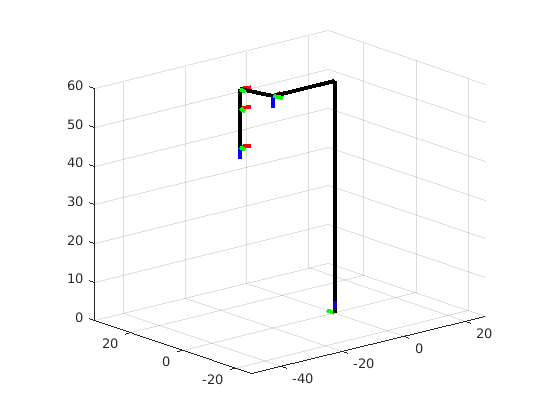

grid on
hold on
view([-40.5 16.8])
    
% Calculate our inverse transformations back to the 0 frame for all
% coordinate frames
H_1_0 = inv(H_0_1);
H_2_0 = inv(H_1_2) * H_1_0;
H_3_0 = inv(H_2_3) * H_2_0;
H_4_0 = inv(H_3_4) * H_3_0;

% Draw each coordinate axis
origin = [0; 0; 0; 1;];
axis_vector_length = 3;
x = [ axis_vector_length; 0; 0; 1; ];
y = [ 0; axis_vector_length; 0; 1; ];
z = [ 0; 0; axis_vector_length; 1; ];

% x0y0z0
draw_coordinate_axis(origin, z, y, z, 'red', 'green', 'blue');
% x1y1z1
origin_1 = H_1_0 * origin;
draw_coordinate_axis(origin_1, H_1_0 * x, H_1_0 * y, H_1_0 * z, 'red', 'green', 'blue');
% x2y2z3
origin_2 = H_2_0 * origin;
draw_coordinate_axis(origin_2, H_2_0 * x, H_2_0 * y, H_2_0 * z, 'red', 'green', 'blue');
% x3y3z3
origin_3 = H_3_0 * origin;
draw_coordinate_axis(origin_3, H_3_0 * x, H_3_0 * y, H_3_0 * z, 'red', 'green', 'blue');
% x4y4z4
origin_4 = H_4_0 * origin;
draw_coordinate_axis(origin_4, H_4_0 * x, H_4_0 * y, H_4_0 * z, 'red', 'green', 'blue');

% Draw the components of the robot next.
% The first part is up d1, and then over a2 over
line('XData', [origin(1) 0], 'YData', [origin(2) 0], 'ZData', [origin(3) d1], 'Color', 'black', 'LineWidth', 3);
line('XData', [0 origin_1(1)], 'YData', [0 origin_1(2)], 'ZData', [d1 origin_1(3)], 'Color', 'black', 'LineWidth', 3);
% From here on out we simply draw straight lines to the next axis.
line('XData', [origin_1(1) origin_2(1)], 'YData', [origin_1(2) origin_2(2)], 'ZData', [origin_1(3) origin_2(3)], 'Color', 'black', 'LineWidth', 3);
line('XData', [origin_2(1) origin_3(1)], 'YData', [origin_2(2) origin_3(2)], 'ZData', [origin_2(3) origin_3(3)], 'Color', 'black', 'LineWidth', 3);
line('XData', [origin_3(1) origin_4(1)], 'YData', [origin_3(2) origin_4(2)], 'ZData', [origin_3(3) origin_4(3)], 'Color', 'black', 'LineWidth', 3);

hold off

### Functions

MATLAB requires all functions be declared at the end of the script. As such, here is our declaration of our only function used - *draw_coordinate_axis*, which draws coordinate axes in the active figure.

function [x_line, y_line, z_line] = draw_coordinate_axis(origin, x, y, z, x_color, y_color, z_color)    
    x_line = line('XData', [origin(1) x(1)], 'YData', [origin(2) x(2)], 'ZData', [origin(3) x(3)], 'Color', x_color, 'LineWidth', 3);
    y_line = line('XData', [origin(1) y(1)], 'YData', [origin(2) y(2)], 'ZData', [origin(3) y(3)], 'Color', y_color, 'LineWidth', 3);
    z_line = line('XData', [origin(1) z(1)], 'YData', [origin(2) z(2)], 'ZData', [origin(3) z(3)], 'Color', z_color, 'LineWidth', 3);
end

## Discussion

This assignment's purpose was to reinforce key components of rigid motions for robotics - rotations and their compositions, homogeneous transformations, and applying them to real robotic designs as seen in **III-3**.

In our first problem, **III-1**, we calculated a rotation $R_3^2$ from two intermediary rotatons, $R_3^1$ and $R_2^1$. This demonstrated an understand of the composition rules of rotations as well as some fundamentals of matrix algebra. Specifically - a matrix multiplied by its inverse is the identity matrix, allowing us to treat unknown matricies as variables themselves.

Our second problem, **III-2**, defines numerous homogengeous transformations from *Figure 1*, and then attempts to use easily defined transformations to find a "path" to a more obtuse homogeneous transformation $H_3^2$. We did this by realizing that homogeneous transformations can be treated as directed graphs, allowing quick visual derivation of unknown transformations from known easily.

Finally our third problem, **III-3**, we look at *Figure 2* and determine a series of rotations without defined values. We create our transformations based on what we observe, and then calculate $H_4^0$. Afterwards, we allow the definition of these values ot be applied to create a generated 3d static image of the robot arm, acting as a visual spot-check of our transformation work.

## Citations

- SPONG, M. W., HUTCHINSON, S., & VIDYASAGAR, M. (2020). *Robot modeling and control*. *2nd edition* Hoboken, NJ, John Wiley & Sons. 